% w1 = tf([1 -2], [1 2 4])
w2 = tf([10 -2 15 -23], [10 12 20 58])

w2 =
 
  10 s^3 - 2 s^2 + 15 s - 23
  ---------------------------
  10 s^3 + 12 s^2 + 20 s + 58
 
Continuous-time transfer function.



k = 3

k = 3

Wopen = w2

Wopen =
 
  10 s^3 - 2 s^2 + 15 s - 23
  ---------------------------
  10 s^3 + 12 s^2 + 20 s + 58
 
Continuous-time transfer function.



Wclose = feedback(k*Wopen, 1)

Wclose =
 
  30 s^3 - 6 s^2 + 45 s - 69
  --------------------------
  40 s^3 + 6 s^2 + 65 s - 11
 
Continuous-time transfer function.



pole(Wopen)

ans =   -1.8339 + 0.0000i
   0.3170 + 1.7499i
   0.3170 - 1.7499i


pole(Wclose)

ans =   -0.1570 + 1.2852i
  -0.1570 - 1.2852i
   0.1640 + 0.0000i


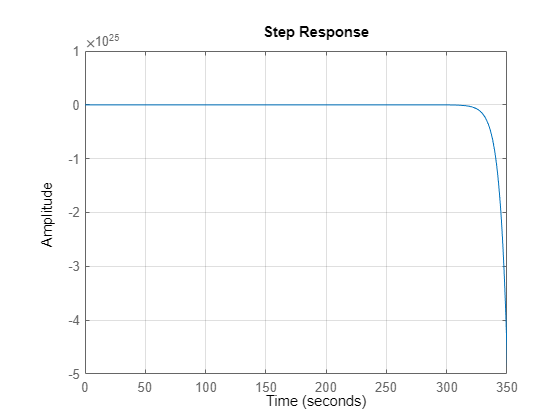

step(Wclose)
grid on

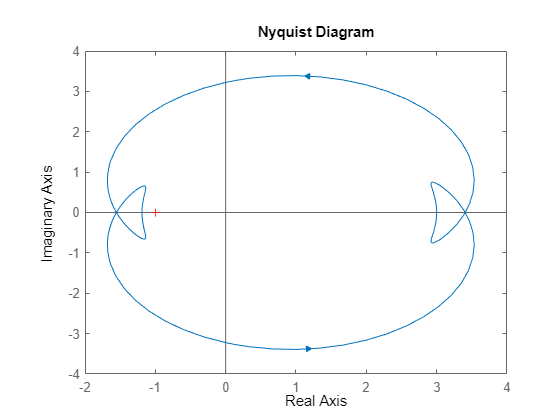

nyquist(k*Wopen)

% plot(out.simout.Time, out.simout.Data)
% grid on
% xlabel("t, с")
% ylabel("Amplitude")
% title("Step Response")
% legend("Closed-loop")